**Adrian Cristian Crisan**

[https://drive.matlab.com/sharing/601df29b-d479-4e17-803b-c136d35f0082](https://drive.matlab.com/sharing/601df29b-d479-4e17-803b-c136d35f0082)

# Solving 3R invers kinematics

## Reviewing 3R robot

clear
mdl_3link3d
R3

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, slowRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


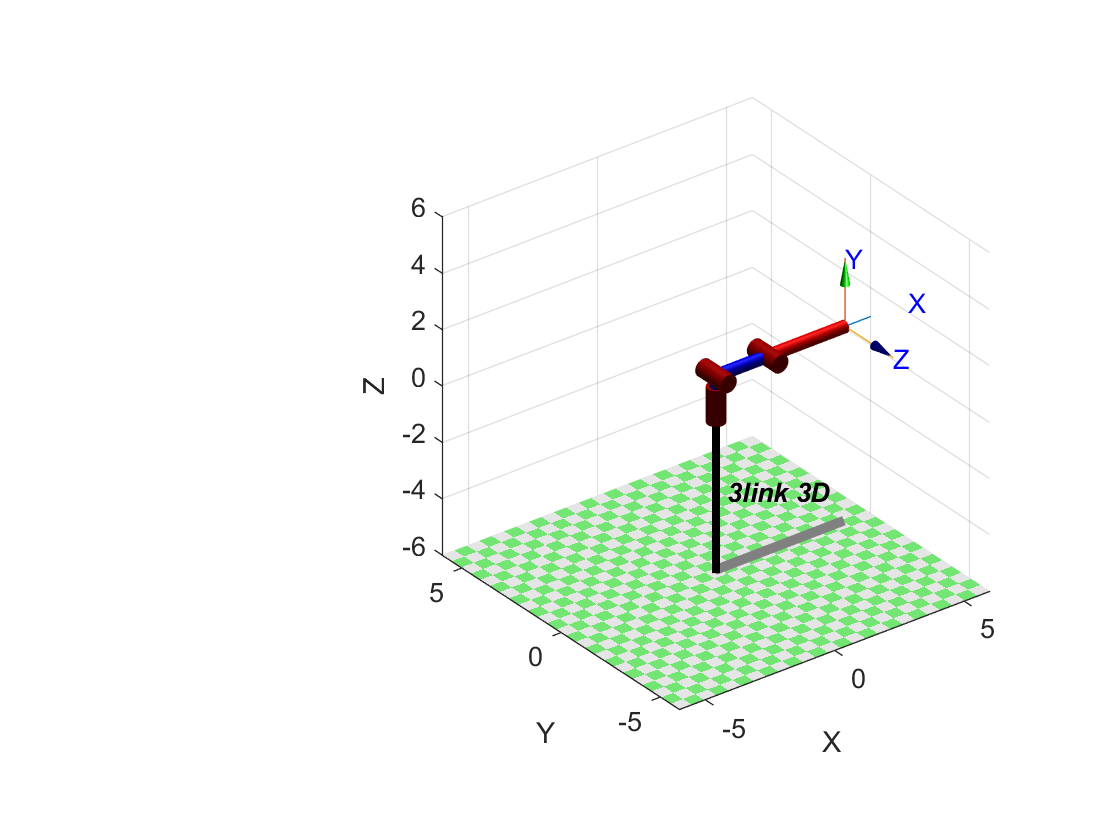

R3.plot([0 0 0])
R3.teach

x = 4.33;
y = 2.5;
z = 1;
L1 = R3.d(1);
L2 = R3.a(2);
L3 = R3.a(3);
UP = 0;
[theta_1, theta_2, theta_3] = ikineFIB(x, y, z, UP, L1, L2, L3);
theta_1_deg = rad2deg(theta_1)

theta_1_deg = 30.0007

theta_2_deg = rad2deg(theta_2)

theta_2_deg = -0.4655

theta_3_deg = rad2deg(theta_3)

theta_3_deg = 0.7758

function [theta_1, theta_2, theta_3] = ikineFIB(x, y, z, up, L1, L2, L3)
h = sqrt(x^2 + y^2);
if h > L2 + L3
    error("Point not reachable")
else
    theta_1 = atan(y/x);
    
    % Calculate the original point for the new reference frame
    T1 = eye(4);
    T2 = eye(4) * trotz(theta_1);
    T3 = T1 / T2 * transl(x, y, z - L1);
    x = T3(1, 4);
    y = T3(2, 4);
    z = T3(3, 4);
    
    beta = atan(z / x);
    gamma = acos((x^2 + z^2 + L2^2 - L3^2) / (2 * L2 * sqrt(x^2 + z^2)));
    theta_3 = acos((x^2 + z^2 - L2^2 - L3^2) / (2 * L2 * L3));
    if (up == 1)
        theta_2 = beta + gamma;
        theta_3 = -theta_3;
    else
        theta_2 = beta - gamma;
    end
    
    
end
end